clear; close all; clc; 
addpath("data/");

load("DatosStepsVariables.mat"); 
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 1; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'

L =    42.6055
  857.6136



Ahat = A-L*C;
Bhat = [B L];
Chat = eye(2);
Dhat = [0];

SysHat = ss(Ahat,Bhat,Chat,Dhat);
SysHat.StateName = {'thetaHat','omegaHat'};
SysHat.OutputName = {'thetaHat','omegaHat'};
SysHat.InputName = {'PWM','theta'};
SysHat = c2d(SysHat,2.5e-3,'tustin')

SysHat =
 
  A = 
             x1        x2
   x1    0.8965  0.002361
   x2    -2.027    0.9892
 
  B = 
             PWM      theta
   x1  2.876e-06     0.1035
   x2   0.002423      2.024
 
  C = 
                  x1       x2
   thetaHat   0.9482  0.00118
   omegaHat   -1.013   0.9946
 
  D = 
                   PWM      theta
   thetaHat  1.438e-06    0.05177
   omegaHat   0.001212      1.012
 
Sample time: 0.0025 seconds
Discrete-time state-space model.



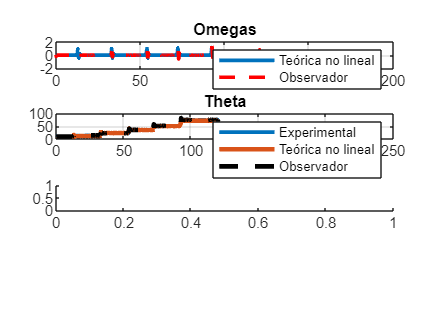


save('LObservador.mat',"L");

addpath("sims/");
data = sim("sims/observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data;
omega_SS = data.omegaSS.Data;

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 
theta_SS = data.thetaSS.Data;

subplot(4, 1, 1); 
plot(t, omega, t, omega_hat, "r--", "LineWidth", 2); 
title("Omegas")
legend("Teórica no lineal", "Observador"); 
grid on; 

subplot(4, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), "LineWidth", 2); 

hold on; 
plot(t, theta, t, theta_hat, "k--", "LineWidth", 2.5); 
hold off; 

title("Theta")
legend("Experimental", "Teórica no lineal", "Observador" ); 
grid on; 

subplot(4,1,3)

plot(t, omega_hat, t, omega_SS, "r--", "LineWidth", 0.5); 

Error using plot
Vectors must be the same length.

subplot(4,1,4)
plot(t,theta_hat,t,theta_SS, "r--", "LineWidth", 0.5)


## Implementación Arduino

L

SysHat =
 
  A = 
             thetaHat  omegaHat
   thetaHat    -42.61         1
   omegaHat    -858.5    -3.334
 
  B = 
                PWM   theta
   thetaHat       0   42.61
   omegaHat  0.9745   857.6
 
  C = 
             thetaHat  omegaHat
   thetaHat         1         0
   omegaHat         0         1
 
  D = 
               PWM  theta
   thetaHat      0      0
   omegaHat      0      0
 
Continuous-time state-space model.



s = tf('s')
integrador =  1/s;
intDiscrete = c2d(integrador,2.5e-3,'tustin')


L =    42.6055
  857.6136


sys

s =
 
  s
 
Continuous-time transfer function.



intDiscrete =
 
  0.00125 z + 0.00125
  -------------------
         z - 1
 
Sample time: 0.0025 seconds
Discrete-time transfer function.



sys =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.

